load ifk.mat

%Discretizing the integral

x = linspace(0.025,0.975,20)'; y=x;
for i=1:20
    for j=1:20 
        G(i,j)=0.05*x(j)*exp(-x(j)*y(i));
    end 
end 
G;
[m,n] = size(G);
[U,S,V] = svd(G);
p=rank(G);
s=diag(S);
sigma = 10^(-4);


### **1.**

Use the L-curve to find a value for $\alpha$. In MATLAB you can use the toolbox regtools. In addition to reporting the value for $\alpha$, submit a figure showing the L-curve. 						

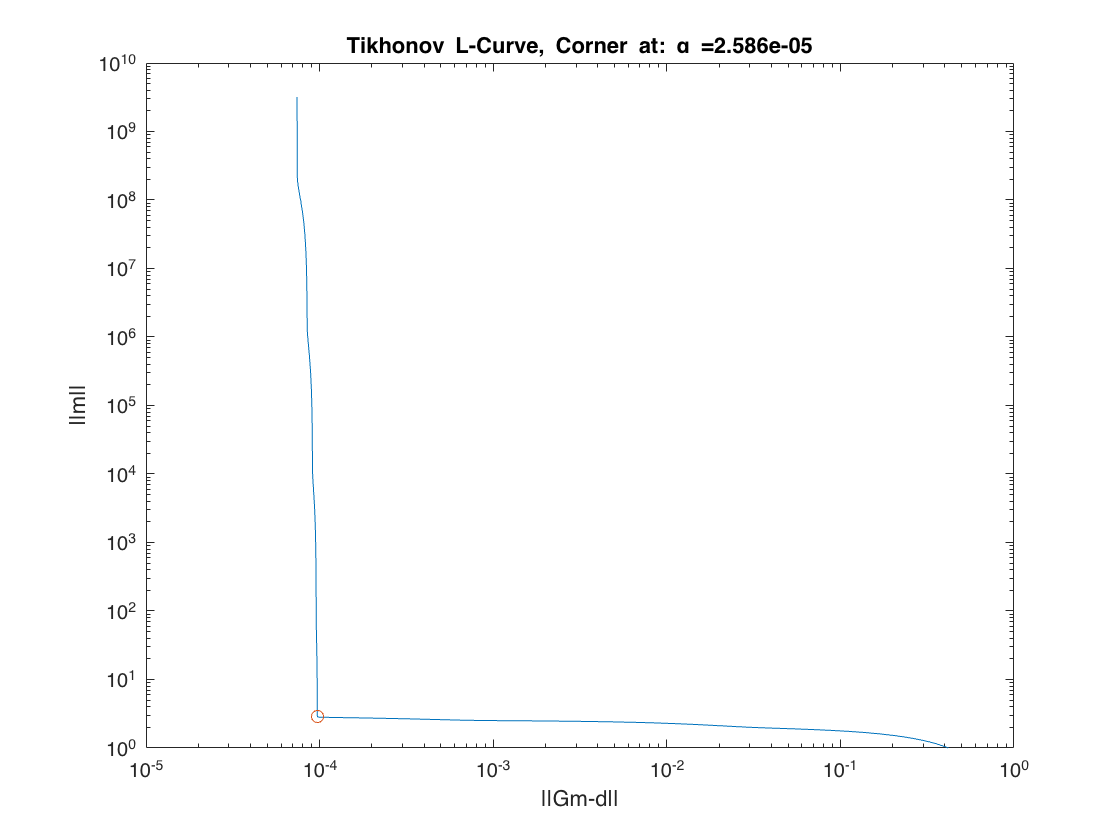

%% Getting the L-curve
figure(1);
[rho,eta,reg_param]=l_curve_tikh_svd(U,diag(S),d,1000); 
[alpha_corner,ireg_corner,kappa]=l_curve_corner(rho,eta,reg_param); loglog(rho,eta)
hold on
loglog(rho(ireg_corner),eta(ireg_corner),'o')
hold off
xlabel('||Gm-d||')
ylabel('||m||')
title(['Tikhonov L-Curve, Corner at: \alpha =',num2str(alpha_corner)]); 

alpha = alpha_corner

alpha = 2.5860e-05

2(a).  Identify a value for $\delta$ and justify your choice. 						

	My choice is based on the residual norm corresponding to the chosen alpha. So based on this we used yhe heuristic approach ($$\sigma \sqrt(m)$$) to give us the value of delta.

delta = sigma*sqrt(m)

delta = 4.4721e-04

2(b)

m_alpha =(G.'*G+alpha^2*eye(20))\G.'*d;

%(( G*m_alpha - d)).'* (( G*m_alpha - d))
(norm( G*m_alpha - d)).^2

ans = 9.4370e-09

2(c)

  Implement a nonlinear solver such as fsolve in MATLAB to find a regularization pa- rameter using the discrepancy principle. This will require creating a nonlinear function f(α) = ∥Gmα − d∥2 − δ and finding α so that f(α) = 0. 						

f = @(alpha) norm(G*((G.'*G+alpha^2*eye(20))\G.'*d) - d)^2 - delta; 
alpha1 = fsolve(f,alpha)


Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


alpha1 = 2.5860e-05

### **3.**	

Consider the regularized discrepancy ∥Gmα − d∥2/σ2 + α2∥mα∥2 ≤ δreg.  

(a) Identify a value for δreg and justify your choice. 		


delta_reg = m

delta_reg = 20

This is based on the fact that we $$‖Gm_{\alpha}-d‖_{2}^{2}$$$/ \sigma^{2}$$+ \alpha^{2}||m_{\alpha}||_{2}^{2}$ is equivalent to the chi-square distribution with m degrees of freedom, hence $\delta_{reg}$ will be equal to the expected value of the chi-square distribution .

(b) Use your values for α from 1 and 2c to calculate ∥Gmα − d∥2/σ2 + α2∥mα∥2. Discuss if these choices of α satisfy the regularized discrepancy you chose in 3a. 	

The choices of $\alpha$ satisfy the regularized discrepancy we chose in 3a, since the values of the regularized discrepancy obtained in 3b are less than the regularized discrepancy we chose in 3a.

m_alpha = @(alpha) (G.'*G+alpha^2*eye(20))\G.'*d;
fun = @(alpha) (norm(G*m_alpha(alpha) - d)^2)/(sigma^2) +(alpha^2)*norm(malpha(alpha))^2; 
Regularized_discrepancy  = fun1(alpha)

Regularized_discrepancy = 0.9437

Regularized_discrepancy1  = fun(alpha1)

Regularized_discrepancy1 = 0.9437

(c) Implement a nonlinear solver such as fsolve in MATLAB to find a regularization param- eter using the regularized discrepancy principle. This will require creating a nonlinear function freg(α) = ∥Gmα − d∥2/σ2 + α2∥mα∥2 − δreg and finding α so that freg(α) = 0. 	

f_reg = @(alpha) (norm(G*m_alpha(alpha) - d)^2)/(sigma^2) +(alpha^2)*norm(malpha(alpha))^2 - delta_reg; 
alpha2 = fsolve(f_reg,alpha)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


alpha2 = 6.7486e-04

### **4.	**

Plot model parameter estimates using Tikhonov regularization with all three values of α on the same graph. Relate the shape of the different graphs to the corresponding values for α. 

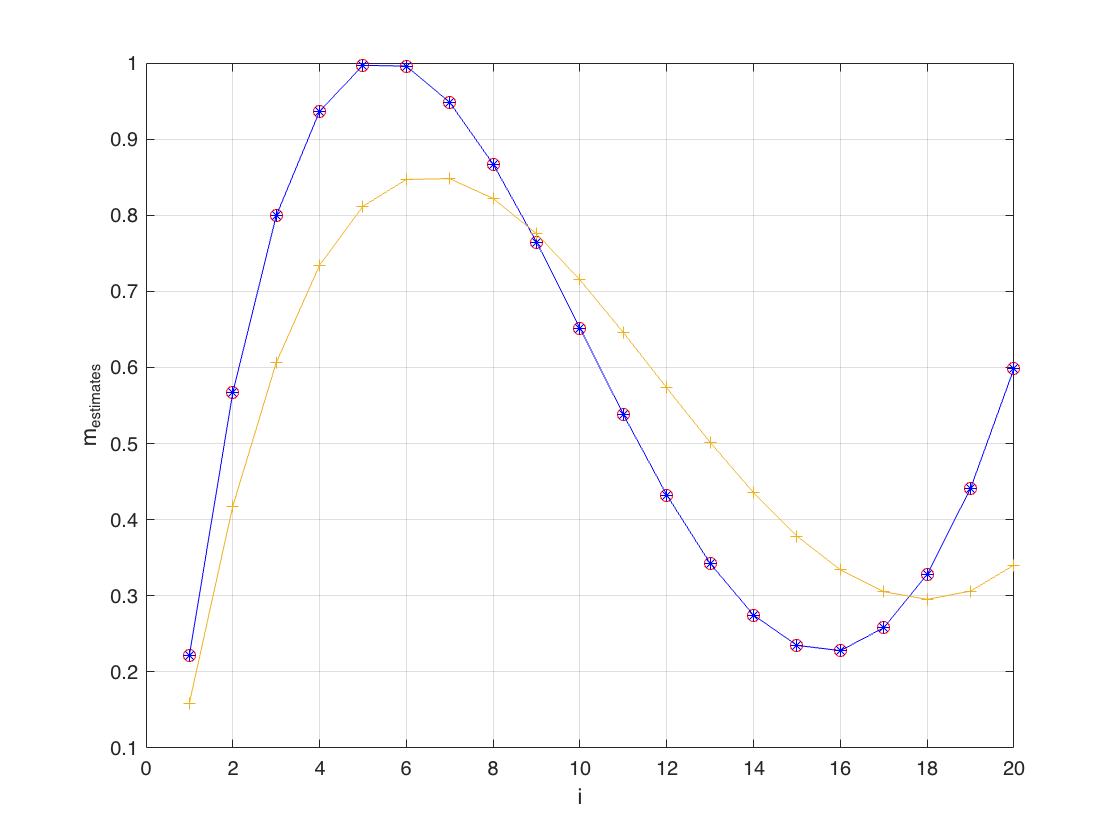

m_alpha =(G.'*G+alpha^2*eye(20))\G.'*d;
m_alpha1 =(G.'*G+alpha1^2*eye(20))\G.'*d;
m_alpha2 =(G.'*G+alpha2^2*eye(20))\G.'*d;
figure(9)
plot(m_alpha,'ro-') 
hold on
plot(m_alpha1,'b*-')
hold on
plot(m_alpha2,'+-')

%plot(mtrue,'o--')
hold off
%title('TSVD model parameter estimates') 
xlabel('i') 
ylabel('m_{estimates}') 
%legend('m_{est} for \alpha = e^{-1}','m_{est} for \alpha = e^{-3}','m_{est} for \alpha = e^{-5}','mtrue')
grid on

Based on the graph, smaller  values of alpha yeilded better curve shapes compared to the larger values.

5.

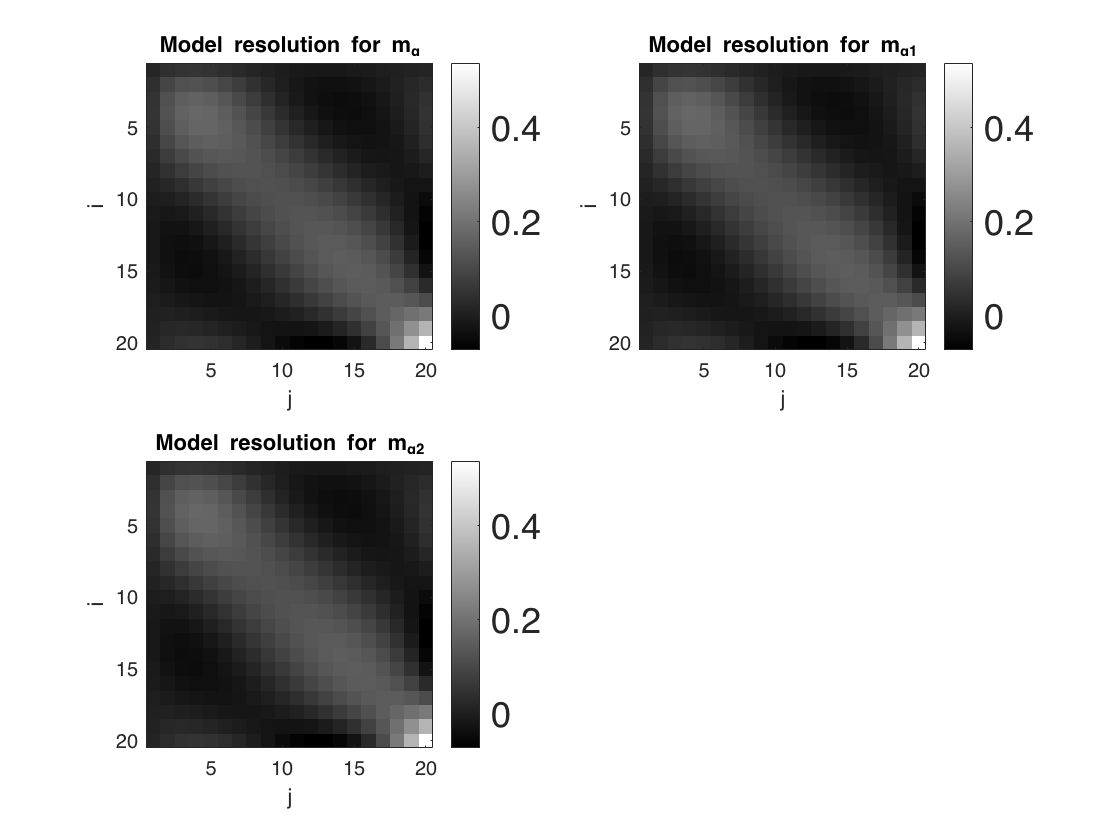

Rm = (G'*G+alpha^2*eye(20))\G' * G;
Rm1 = (G'*G+alpha1^2*eye(20))\G' * G;
Rm2 = (G'*G+alpha2^2*eye(20))\G' * G;

figure(10)
clf
colormap('gray')
subplot(2,2,1)
imagesc(Rm )
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Model resolution for m_{\alpha}');
subplot(2,2,2)
imagesc(Rm1 )
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Model resolution for m_{\alpha1}');
subplot(2,2,3)
imagesc(Rm1 )
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Model resolution for m_{\alpha2}');

	5. The resolution is best at diagonal entries of the parameter estimates, and is worse at off diagonal entries. The model parameters can be well resolved, if we use better methods of finding alpha, since the estimates depend on the values of alpha. Therefore better values of alpha will yeild good parameter estimates, thereby achieving better resolution.